# E8

# Descripció de regions

close all
hold off
BW = rgb2gray(imread('Abecedari.png')) < 200;
imshow(BW);

BWU = BW; 
BWU(end/2:end,:) = 0;

BWD = BW;
BWD(1:end/2,:) = 0;


CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD)

CCD = struct with fields:
    Connectivity: 8
       ImageSize: [253 1632]
      NumObjects: 26
    PixelIdxList: {1×26 cell}


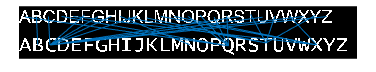


propsU = regionprops('table',CCU,'Centroid','BoundingBox','Circularity','Solidity','Extent','EulerNumber');
propsD = regionprops('table',CCD,'Centroid','BoundingBox','Circularity','Solidity','Extent','EulerNumber');

NumObj = CCU.NumObjects; % nombre d'objectes trobats a la fila de dalt

% Construim el vector de caracteristiques
% FU = [propsU.BoundingBox(3)/propsU.BoundingBox(4)];
% FD = [propsD.BoundingBox(3)/propsD.BoundingBox(4)];
FU = [propsU.Circularity, propsU.Solidity, propsU.Extent, propsU.EulerNumber];
FD = [propsD.Circularity, propsD.Solidity, propsD.Extent, propsD.EulerNumber];

% normalitzem per columnes segons el seu valor màxim
FU = FU./max(FU);
FD = FD./max(FD);

Assig = dsearchn(FD,FU);

hold on
for i = 1:NumObj
    line( [propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)],[propsU.Centroid(i,2), propsD.Centroid(Assig(i),2)]);
end

hold off

% busquem les assignacions basnt-nos en la min distancia euclidea
A = zeros(NumObj,NumObj);
for i = 1: NumObj
    for j = 1: NumObj
        A(j,i) = norm(FU(i,:) - FD(j,:));
    end
end

Assig = zeros([NumObj 1]);

% realitzem l'aparellament i eliminem els candidats aparellats
for k = 1:NumObj
    [Amins, idx] = min(A);      % minims de cada columna i la fila
    [Amin, Ai] = min(Amins);    % minim global i la columna
    Aj = idx(Ai);               % trobem fila i columna del minim
    Assig(Ai) = Aj;             % assignem l'aparellament
    A(Aj,:) = Inf;              % eliminem l'aparellament a la matriu de dsitàncies
    A(:,Ai) = Inf;
end

### Fourier

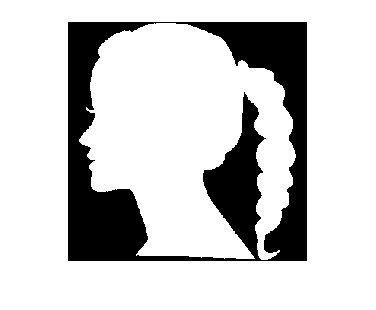

close all
im = imread('head.png');
im = imresize(im,0.5);
imshow(im);

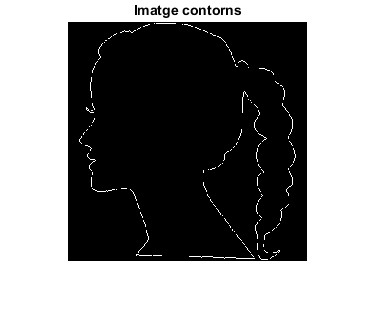


% Contorns exteriors
cont = xor(im, imerode(im, strel('disk', 1)));
figure, imshow(cont), title('Imatge contorns')

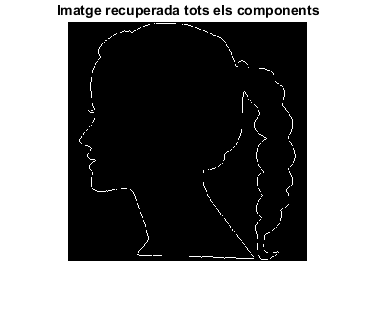

[fila, col] = find(cont, 1); % busquem el primer pixel a 1
B = bwtraceboundary(cont, [fila col], 'E');

% Coordenades centrades
mig = mean(B);
Bc = B - mig; % traslladem a l'origen
s = Bc(:, 1) + Bc(:,2) * 1i; % passem a complexes

% Transformada de fourier
z = fft(s);

ss = ifft(z);

aux = zeros(size(im));
files = round(real(ss) + mig(1)); 
cols = round(imag(ss) + mig(2));

aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux), title('Imatge recuperada tots els components');

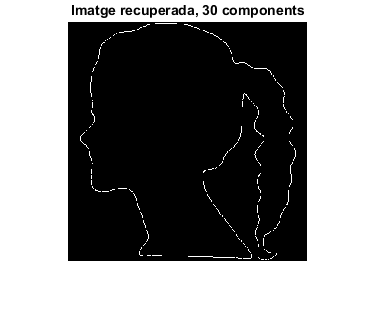


N = 50;
zz = z;

zz(N+1:end-N) = 0;

ss = ifft(zz);

aux = zeros(size(im));
files = round(real(ss) + mig(1)); 
cols = round(imag(ss) + mig(2));

aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux), title('Imatge recuperada, 30 components');